# Lab 7

In this lab we would like to identify and isolate the signals that HERA searches for. The signal from the sky is known to be very steady in time, as opposed to the background contamination which can vary based on the time of day or rotation of the Earth.

clear;
clc;

load('hera_data.mat')
%Use just XX polarized light, as it has the highest magnitude of visibility
pol = 1;
range = 1:1378;
%Make an array of complex numbers from the visdata struct
visdata_re = visdata.r(pol, :, 1, :);
visdata_im = visdata.i(pol, :, 1, :);
visdata_complex = complex(visdata_re, visdata_im);

visdata_mag = abs(visdata_complex);
visdata_time1 = visdata_mag(:, :, 1, range);

We are given data from all 1,378 baselines for 60 instances in time, which is represented by a vector of length 1,378 * 60 (where every 1,378 entries represents a diferent value of time). Again, time is given in units of Julian days, which is shown [here](http://reionization.org/manual_uploads/HERA069_IDR2.2_Memo_v2.html). The time t=1 corresponds to the first entry in time_array, and is the time which corresponds to the first 1,378 entries in the [baseline pairs * times] column of the array visdata:

time_1 = time_array(1);
fprintf('%.6f\n', time_1)

2458108.125574


By plotting the complex magnitude of the visibility of the first 1,378 baselines in this vector against frequency, we can create a plot which shows the readings of all baselines at time t = 1:

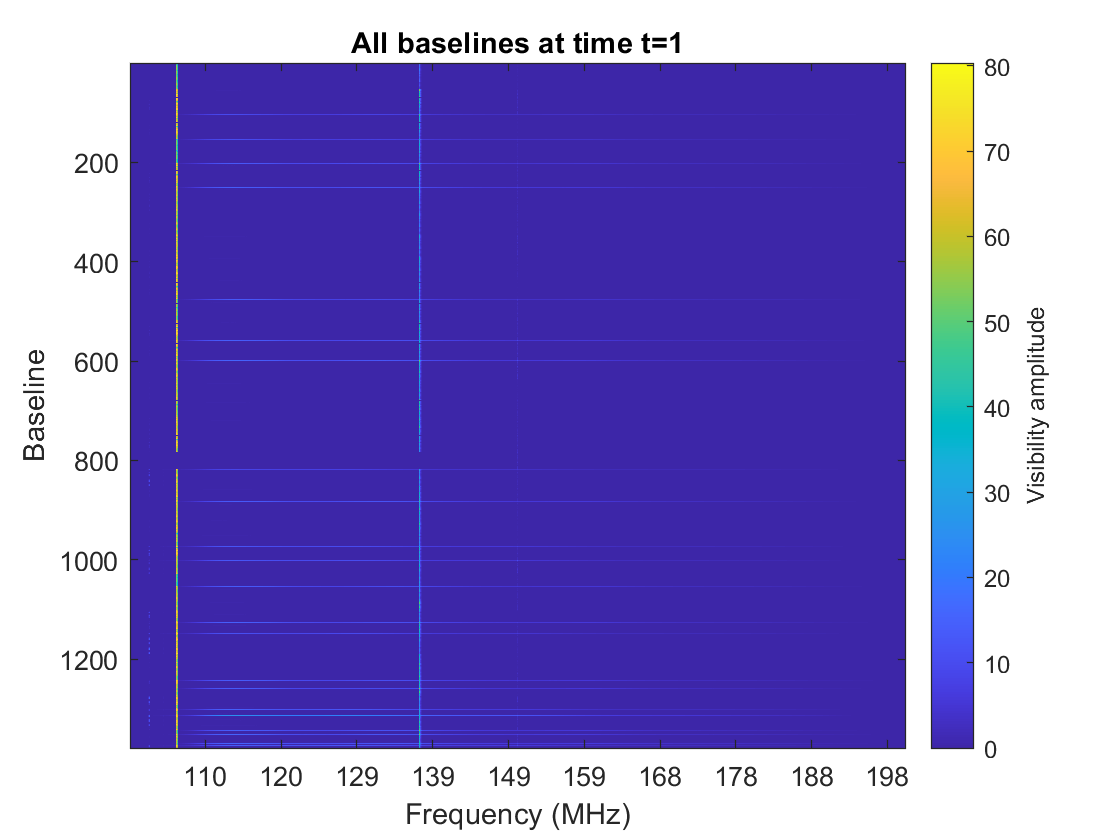

%Plot the raw data for time 1
clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

We can remove these horizontal streaks of data, which correspond to baselines comprised of one antenna being correlated with itself. To do this, we simply remove all data with indices corresponding to baselines with the same antenna paired with itself.

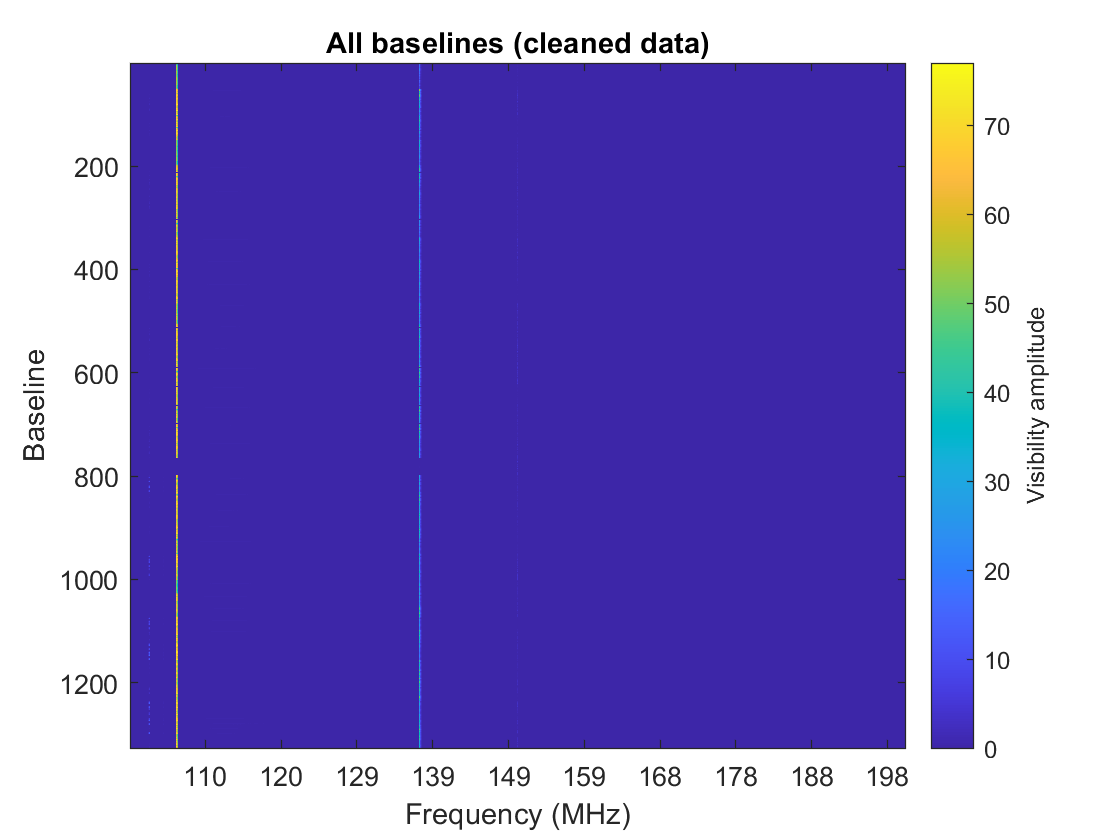

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);
clean_img = squeeze(clean_data)';
clf;
imagesc(clean_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines (cleaned data)')

We can observe the different frequencies at which some sort of appreciable data is recieved by the array by plotting the sum of the visibility amplitudes across all these baselines versus the range of frequencies:

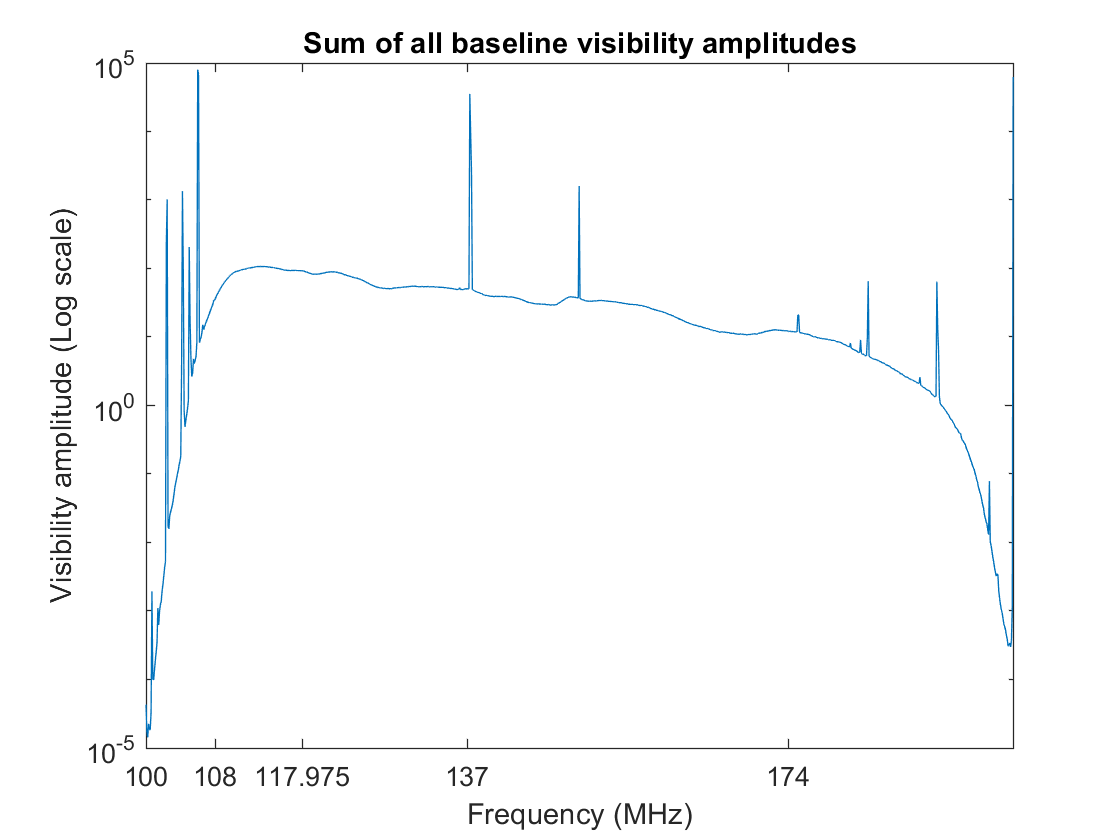

amplitude_all = sum(clean_img, 1);
clf;
semilogy(freq_array ./ 1e6, amplitude_all(1:1024))
xticks([100 108 117.975 137 174])
xlabel('Frequency (MHz)');
ylabel('Visibility amplitude (Log scale)')
title(['Sum of all baseline visibility amplitudes'])

From this plot, we can also observe some anomalous data patterns at the high and low ends of the frequency spectrum. These patterns imply that the visibility amplitude drops significantly at frequencies $f<~110\;\mathrm{MHz}$ and $f>~180\;\mathrm{MHz}$. This may be due to the radio frequency allocation in South Africa: frequencies less than 108 MHz and greater than 174 MHz are primarily used for broadcasting, which we may assume to correspond to radio or television broadcasting from sources at ground level. On the other hand, frequencies that are within this range of values are primarily used for aeronautical and satellite communication with the Earth. Since the HERA antennas are aimed up at the sky, the background is likely more influenced by electromagnetic radiation from above rather than from sources on the ground, such as television and radio broadcating antennas.

Here is a section of the South African frequency allocation chart overlaid on the plot above.

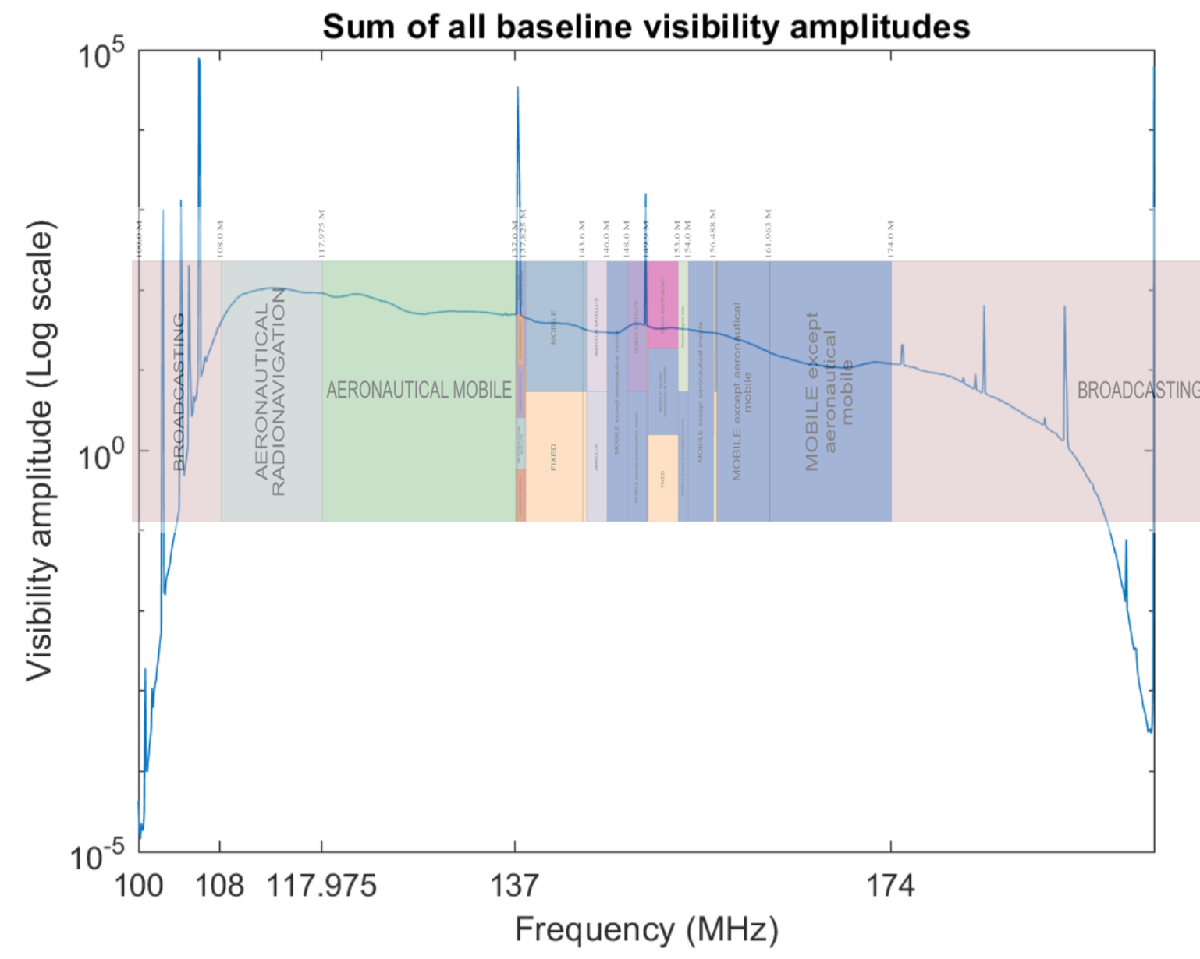

Now we would like to observe the data recieved by a single baseline over several instances of time. 

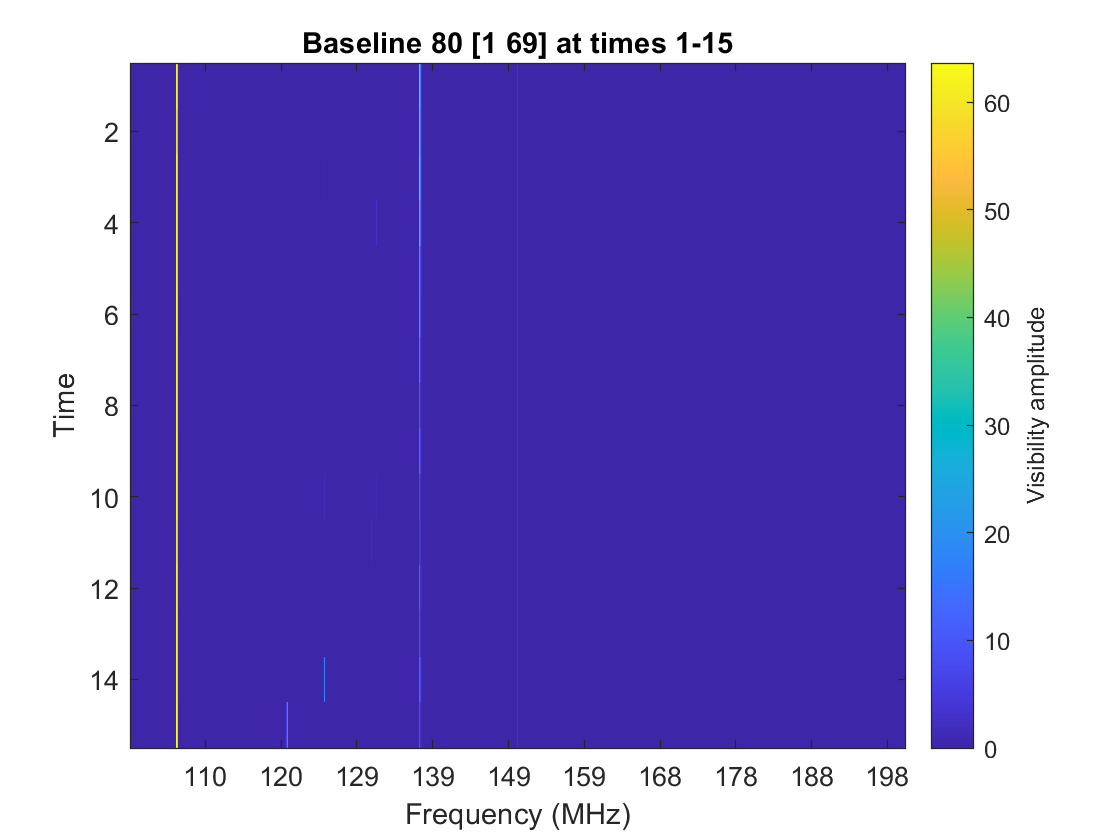

%Choose a specific pair of antennas (X, Y), or just choose a baseline N
baseline = 80;
if isscalar(baseline)
    bl = baseline;
    antennas = baselines(bl, :);
else
    bl = find(ismember(baselines, baseline, "rows"))
    antennas = baseline;
end
baseline_waterfall_data = visdata_mag(:, :, :, bl:1378:end);
waterfall_img = squeeze(baseline_waterfall_data)';

clf;
imagesc(waterfall_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title(['Baseline ' num2str(bl) ' ' mat2str(antennas) ' at times 1-15']);

The signal from this baseline looks like it varies in time. Short spikes of visibility appear in the 120-130 MHz range from t=14 to t=15, and the signal at ~137 MHz seems to decrease in intensity over time. We expect that the signals HERA is searching for (usually signals from distant radio galaxies) are very steady in time, remaining stable over millions of years, so these patterns are likely sources of background, not the signal HERA is searching for.

We can also plot a histogram of the visibility data with bins of different frequencies.

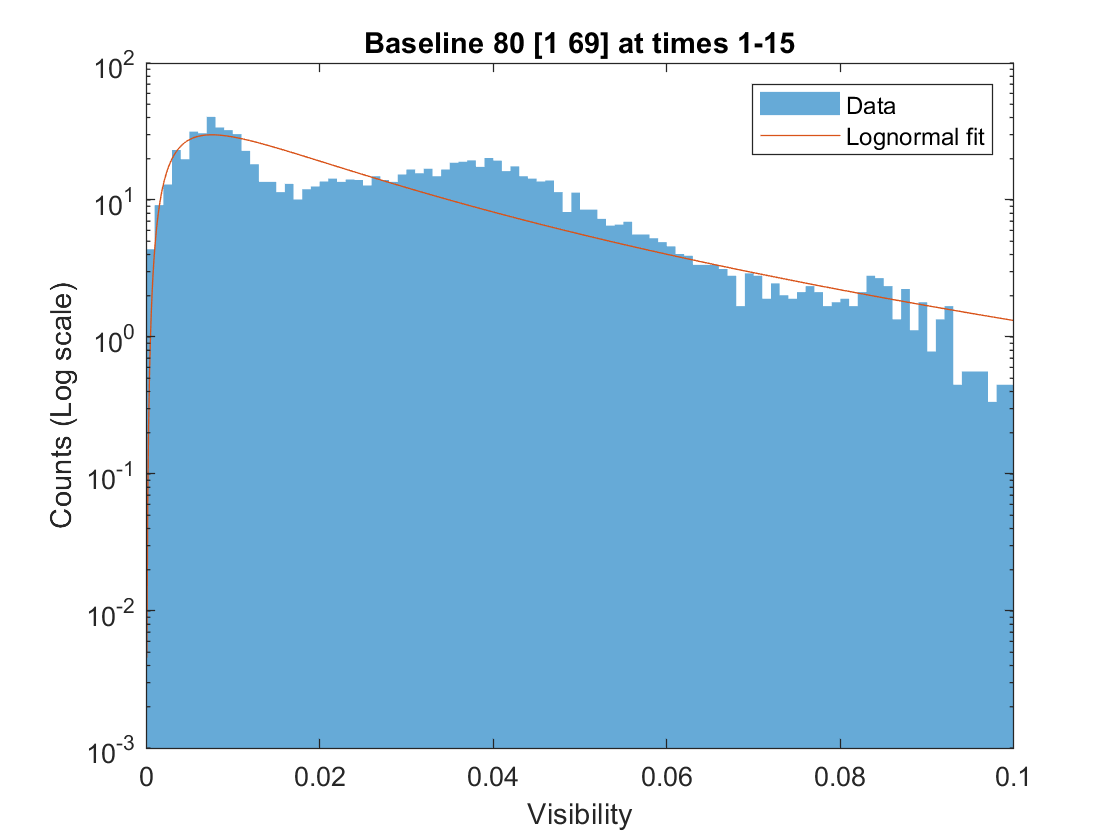

clf;
nbins = 100;
waterfall_img_limit = waterfall_img(:, 200:800);
maxval = 0.1;
histogram(waterfall_img_limit(waterfall_img_limit < maxval), nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

PD = fitdist(reshape(waterfall_img_limit, [], 1), 'Lognormal');
xs = linspace(0, maxval, 1000);
ys = lognpdf(xs, PD.mu, PD.sigma);

plot(xs, ys);

set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts (Log scale)');
xlim([0 maxval])
title(['Baseline ' num2str(bl) ' ' mat2str(antennas) ' at times 1-15']);
legend('Data', 'Lognormal fit');

It would seem that a lognormal fit would best describe this distribution of visibility amplitudes, but as shown above, even this is not a very accurate fit.

For this particular baseline, we can also plot the visibility magnitude averaged over time; 15 time intervals, to be exact. 

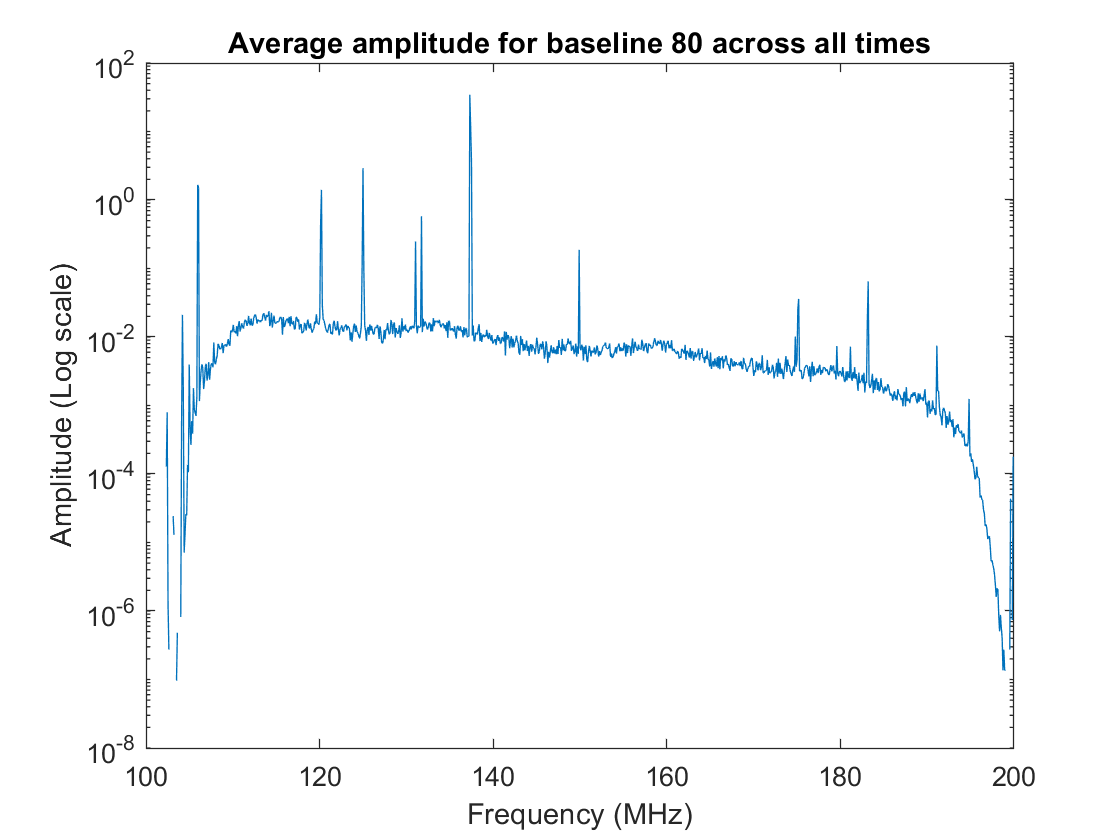

vis = squeeze(visdata_complex);

%Differenced times for time 1

diffs = zeros(1024, 14, 1378);
for ii = 1:1378
    diffs(:, :, ii) = diff(vis(:, ii:1378:end), 1, 2);
end

amplitude1 = mean(abs(diffs(:, :, bl)), 2);
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title(['Average amplitude for baseline ' num2str(bl) ' across all times'])

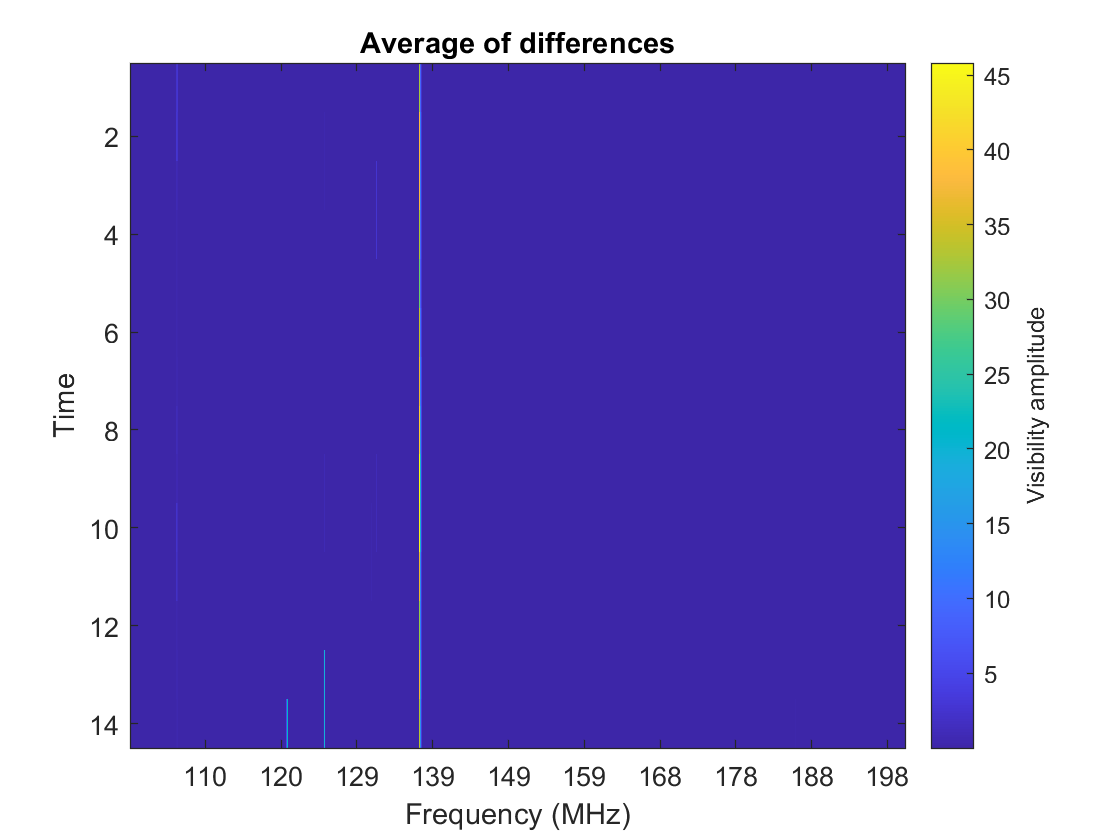

%remove vaa from data
clean_diffs = abs(diffs(:, :, ~commonpair_indices));

averages = mean(abs(clean_diffs), 3);
clf;
imagesc(averages');
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
yticks('auto');
ylabel('Time');
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Average of differences');

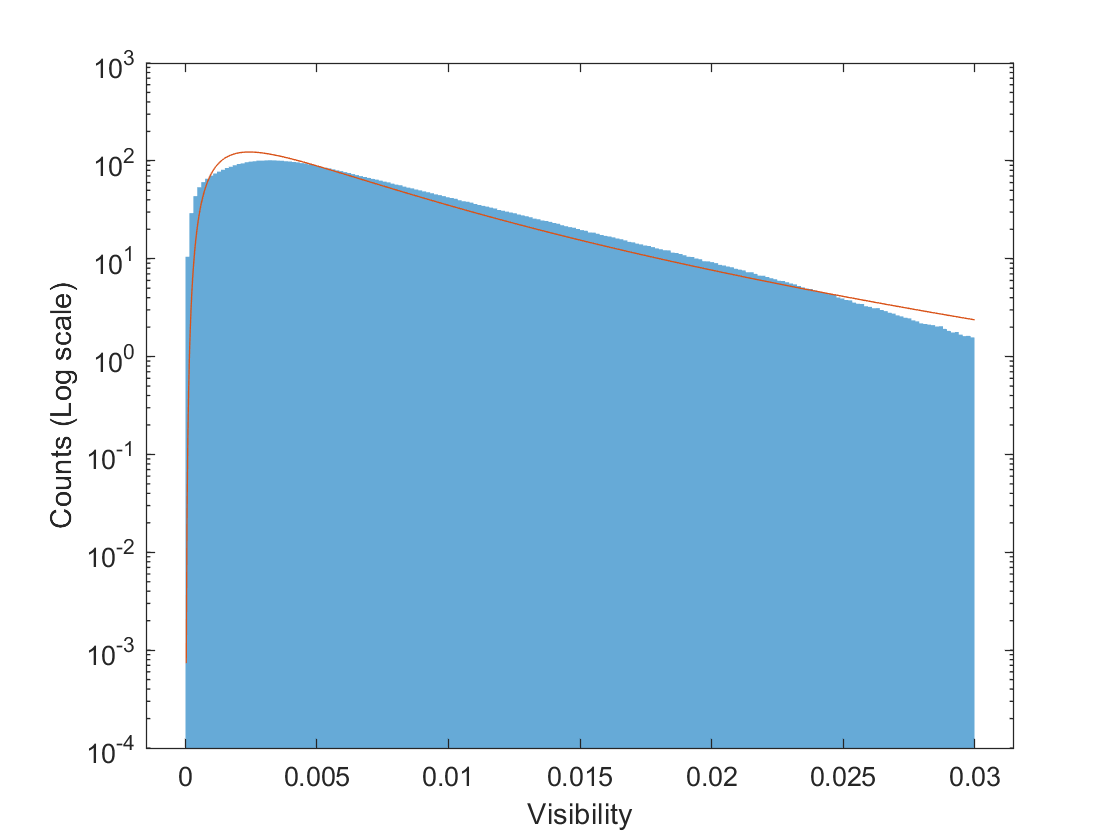

%Average per frequency
avg_val = mean(averages, 1);
clf;
nbins = 200;
maxval = 0.03;
clean_diffs_lim = clean_diffs(200:800, :, :);
cl = clean_diffs_lim(clean_diffs_lim < maxval);
histogram(cl, nbins, 'EdgeColor', 'none', 'Normalization', 'pdf'), hold on;

PD = fitdist(reshape(cl, [], 1), 'Lognormal');
xs = linspace(0, maxval, 1000);
ys = lognpdf(xs, PD.mu, PD.sigma);

plot(xs, ys)
set(gca, 'YScale', 'log')
xlabel('Visibility');
ylabel('Counts (Log scale)');

%xlim([0 0.05])
%xlim([0 maxval])


% times_vis = [];
% for ii = 1:1378
%     times_vis = [times_vis; vis(:, ii:1378:end)];
% end
% times_vis